# Graphing Monomials and Polynomial of the 3rd Degree

**Back to **[**Intro Math for Econ**](https://math4econ.github.io/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Monomial

Functions of the form:


$$a\cdot x^k$$


are monomials.

- $a$ is any real number, it is the coefficient.

- $k$ is a positive integer, it is the degree of the monomial

## Polynomial

Monomials added up together are polynomials


$$a + b \cdot x + c \cdot x^2 + d \cdot x^3 + e \cdot x^4$$


The coefficients $a,b,c,d,e$ above could be positive or negative. 

- **Degree of Polynomial**: We say that this polynomial has degree of 4. You find the largest degree monomial in the polynomial, and its degree is the degree of the whole polynomial.

## Graphical Monomial Examples

Take a look at the function below, matlab makes it very easy to plot functions. You can see that when we shift the coefficient for the monomial, it rescales the function but does not change the ordinality.

Monomial when a = 0.75, a = 1, and a = 1.25:

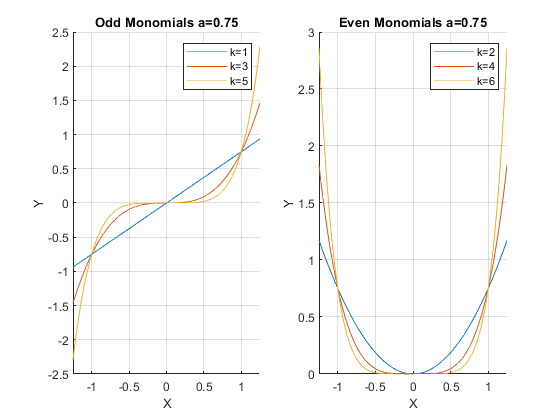

clear all;
a = 0.75;
ffi_monomial_graph(a)

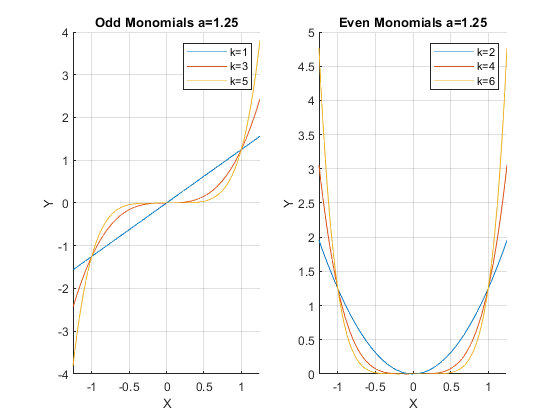

a = 1.25;
ffi_monomial_graph(a)

## Polynomial of Degree Three

Some outcome is a function of a polynomial of degree three, what does this look like?

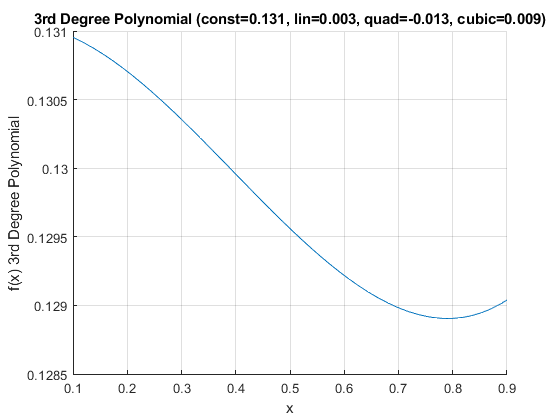

[fl_lower_bound, fl_uppper_bound] = deal(0.1, 0.9);
% Graph 1
[fl_constant, fl_lin, fl_quad, fl_cubic] = deal(0.131047762,0.002654614,-0.012944615,0.0086788);
ffi_poly3rd_degree(fl_lower_bound, fl_uppper_bound, fl_constant, fl_lin, fl_quad, fl_cubic);

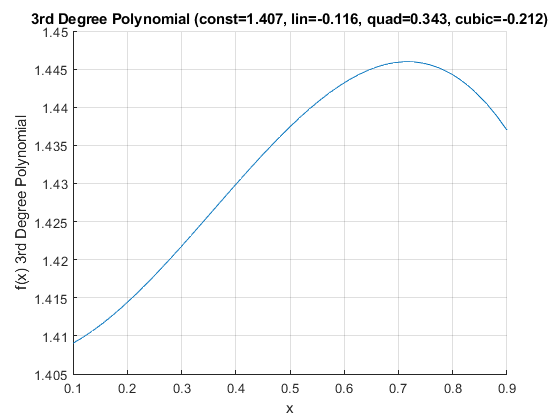

% Graph 2
[fl_constant, fl_lin, fl_quad, fl_cubic] = deal(1.406975108, -0.115556127, 0.343419845, -0.212016167);
ffi_poly3rd_degree(fl_lower_bound, fl_uppper_bound, fl_constant, fl_lin, fl_quad, fl_cubic);

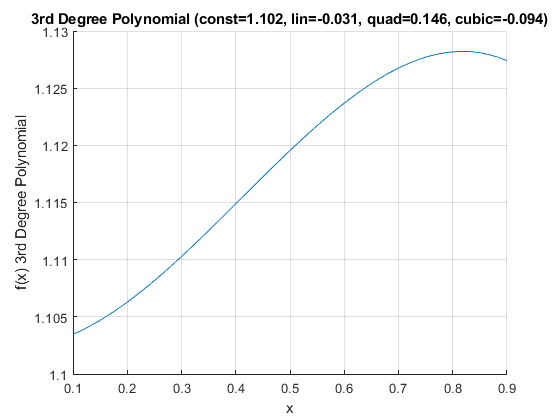

% Graph 3
[fl_constant, fl_lin, fl_quad, fl_cubic] = deal(1.102411416, -0.03056625, 0.146249875, -0.094270393);
ffi_poly3rd_degree(fl_lower_bound, fl_uppper_bound, fl_constant, fl_lin, fl_quad, fl_cubic);

## Mononomials Function

When we program, we can write functions, which have parameters

function ffi_monomial_graph(a)

% Define a symbolic monomial
syms x k
f(x, k) = a*x^k;

% Graph equation
close all;
figure();

%Subplot 1
subplot(1,2,1)
% Create minimum x and maximum x point where to draw the graph
x_lower_bd = -1.25;
x_upper_bd = +1.25;
% keep all figures, do not drop previous
hold on;
% Draw the function
ak1 = fplot(@(x) f(x, 1), [x_lower_bd, x_upper_bd]);
ak3 = fplot(@(x) f(x, 3), [x_lower_bd, x_upper_bd]);
ak5 = fplot(@(x) f(x, 5), [x_lower_bd, x_upper_bd]);
% Label
xlabel('X');
ylabel('Y');
xlim([x_lower_bd, x_upper_bd])
title(['Odd Monomials a=',num2str(a)])
legend('k=1','k=3', 'k=5');
grid on

% Subplot 2
subplot(1,2,2)
% Create minimum x and maximum x point where to draw the graph
x_lower_bd = -1.25;
x_upper_bd = +1.25;
% keep all figures, do not drop previous
hold on;
% Draw the function
ak2 = fplot(@(x) f(x, 2), [x_lower_bd, x_upper_bd]);
ak4 = fplot(@(x) f(x, 4), [x_lower_bd, x_upper_bd]);
ak6 = fplot(@(x) f(x, 6), [x_lower_bd, x_upper_bd]);
% Label
xlabel('X');
ylabel('Y');
xlim([x_lower_bd, x_upper_bd])
title(['Even Monomials a=', num2str(a)])
legend('k=2','k=4', 'k=6');
grid on
end


## Polynomial of Degree Three Function

A function for graphing polynomial of the 3rd Degree.

function ffi_poly3rd_degree(fl_lower_bound, fl_uppper_bound, fl_constant, fl_lin, fl_quad, fl_cubic)

% Define a symbolic monomial
syms x
f(x) = fl_constant + fl_lin*x^2 + fl_quad*x^2 + fl_cubic*x^3;

% Graph equation
close all;
figure();

hold on;
% Draw the function
fplot(@(x) f(x), [fl_lower_bound, fl_uppper_bound]);
% Label
xlabel('x');
ylabel('f(x) 3rd Degree Polynomial');
xlim([fl_lower_bound, fl_uppper_bound])
% Title
ar_params = [fl_constant, fl_lin, fl_quad, fl_cubic];
ar_st_parms_names = ["const", "lin", "quad", "cubic"];
st_rounding = '.3f';
st_title_main = "3rd Degree Polynomial";
ar_st_params = strcat(ar_st_parms_names, compose(strcat("=%", st_rounding), ar_params));
st_param_pasted = strjoin(ar_st_params, ', ');
st_title_wth_params = strcat(st_title_main, ' (', st_param_pasted, ')');
title(st_title_wth_params);
grid on

end